clc; clear; close all;

%% Alunos: Felipe Ferrer Sorrilha e Guilherme Pança Franco

%% Configurações
% Nomes dos arquivos que vamos analisar - do dataset da Paderborn
arq_normal = 'N09_M07_F10_K001_1.mat';  % Motor saudável, sem defeito
arq_falha  = 'N09_M07_F10_KA04_1.mat';  % Motor com falha no anel externo do rolamento
fs = 64000;  % A gente tá amostrando a 64kHz 

%% Carregar arquivos
% Primeiro carrega o motor saudável
D = load(arq_normal);  % Abre o arquivo .mat
fn = fieldnames(D);  % Pega o nome da estrutura dentro (tem uns nomes estranhos)
struct_normal = D.(fn{1});  % Acessa a estrutura principal
sinal_normal = double(struct_normal.Y(1).Data(:));  % Pega os dados de corrente

% Agora faz a mesma coisa pro motor com defeito
D = load(arq_falha);  
fn = fieldnames(D);
struct_falha = D.(fn{1});
sinal_falha = double(struct_falha.Y(1).Data(:));

% Igualar tamanhos
% As vezes os sinais têm comprimentos diferentes, então a gente padroniza
Lmin = min(length(sinal_normal), length(sinal_falha));  % Pega o menor tamanho
sinal_normal = sinal_normal(1:Lmin);  % Corta o normal pro tamanho menor
sinal_falha = sinal_falha(1:Lmin);    % Corta a falha igual

%% Pré-processamento
% Tira o nível DC (componente contínua) - tipo o "viés" do sinal
sinal_normal = detrend(sinal_normal, 'constant');
sinal_falha  = detrend(sinal_falha, 'constant');

% Filtro passa-baixa pra cortar o ruído de alta frequência
fc = 2000; % Corta tudo acima de 2kHz
[b,a] = butter(6, fc/(fs/2), 'low');  % Filtro Butterworth de 6ª ordem
s_norm_f = filtfilt(b,a,sinal_normal);  % Aplica filtro sem distorcer fase
s_falha_f = filtfilt(b,a,sinal_falha);

%% Estimativa espectral com Welch
% Utilizamos Welch porque ele divide o sinal em pedaços e tira a média,
% funciona tipo uma FFT
nfft = 2^nextpow2(65536);  % Tamanho da FFT como potência de 2 (fica mais rápido)
window = hamming(8192);  % Janela de Hamming de 8192 pontos
noverlap = round(0.5*length(window));  % Janelas se sobrepõem 50%

% Calcula a densidade espectral de potência (PSD)
[psd_norm, f] = pwelch(s_norm_f, window, noverlap, nfft, fs);  % PSD do normal
[psd_falha, f] = pwelch(s_falha_f, window, noverlap, nfft, fs);  % PSD da falha

%% Plot: zoom na fundamental 
% Vamos fazer uma figura com 6 gráficos (3 linhas, 2 colunas)
figure('Color','w','Position',[100 100 1000 700]);  % Figura branca, 1000x700 pixels

% Primeiro gráfico: Espectro da corrente (MCSA tradicional)
subplot(3,2,1);
plot(f,10*log10(psd_norm),'b'); hold on;  % Normal em azul
plot(f,10*log10(psd_falha),'r--');  % Falha em vermelho tracejado
xlim([40 80]); grid on;  % Zoom na região da rede (60Hz ± 20Hz)
title('MCSA (PSD, zoom 40-80 Hz)'); 
xlabel('Frequência (Hz)'); ylabel('PSD (dB/Hz)');
legend('Normal','Falha');

%% Envelope pelo Hilbert
% A demodulação por envelope é tipo pegar a forma do sinal
env_norm = abs(hilbert(s_norm_f));  % Envelope do normal
env_falha = abs(hilbert(s_falha_f));  % Envelope da falha

% Filtro passa-baixa no envelope pra pegar só as baixas frequências
fc_env = 100;  % Corta em 100Hz
[be, ae] = butter(4, fc_env/(fs/2), 'low');  % Filtro de 4ª ordem
env_norm_f = filtfilt(be, ae, env_norm);  % Envelope filtrado do normal
env_falha_f = filtfilt(be, ae, env_falha);  % Envelope filtrado da falha

% Calcula PSD dos envelopes
[psd_env_n, fenv] = pwelch(env_norm_f, window, noverlap, nfft, fs);
[psd_env_f, fenv] = pwelch(env_falha_f, window, noverlap, nfft, fs);

% Segundo gráfico: Espectro do envelope
subplot(3,2,2);
plot(fenv, 10*log10(psd_env_n), 'b'); hold on;
plot(fenv, 10*log10(psd_env_f), 'r');
xlim([0 100]); grid on;  % Foca nas baixas frequências (0-100Hz)
title('Espectro do Envelope (PSD)'); 
xlabel('Freq (Hz)'); ylabel('PSD (dB/Hz)');
legend('Envelope Normal','Envelope Falha');

%% Métricas básicas
fprintf('========================================\n');


% RMSE entre espectros - mede o quanto os espectros são diferentes
rmse_psd = sqrt(mean((psd_norm - psd_falha).^2));
fprintf('1. RMSE entre espectros PSD: %.6e\n', rmse_psd);

1. RMSE entre espectros PSD: 5.513342e+00


% RMSE = 5.513342 (isso apareceu quando rodamos)

% Energia na faixa 0-100 Hz do envelope
idx_env = fenv <= 100;  % Índices das frequências até 100Hz
if sum(idx_env) > 0  % Se tem dados nessa faixa
    energia_env_norm = sum(psd_env_n(idx_env));  % Energia do envelope normal
    energia_env_falha = sum(psd_env_f(idx_env));  % Energia do envelope com falha
    if energia_env_norm > 0  % Pra não dividir por zero
        aumento_env = (energia_env_falha - energia_env_norm)/energia_env_norm*100;
        fprintf('2. Aumento energia envelope 0-100Hz: %.2f%%\n', aumento_env);
    else
        aumento_env = 0;
        fprintf('2. Energia do envelope normal muito baixa\n');
    end
else
    aumento_env = 0;
    fprintf('2. Faixa do envelope não disponível\n');
end

2. Aumento energia envelope 0-100Hz: -70.26%



%% Detecção de picos 40-80Hz
% Procura os picos ao redor da frequência fundamental (60Hz)
froi = f>=40 & f<=80;  % Region Of Interest: região que a gente quer olhar
if sum(froi) > 0  % Se tem dados nessa região
    % Acha os picos no sinal normal
    [PksN, locsN] = findpeaks(psd_norm(froi), f(froi), 'MinPeakProminence', max(psd_norm(froi))/50);
    % Acha os picos no sinal com falha  
    [PksF, locsF] = findpeaks(psd_falha(froi), f(froi), 'MinPeakProminence', max(psd_falha(froi))/50);
    
    % Terceiro gráfico: Picos detectados
    subplot(3,2,3);
    plot(f(froi), 10*log10(psd_norm(froi)),'b'); hold on;
    plot(f(froi), 10*log10(psd_falha(froi)),'r--');
    plot(locsN, 10*log10(PksN), 'bo');  % Picos normais com bolinhas azuis
    plot(locsF, 10*log10(PksF), 'r^');  % Picos da falha com triângulos vermelhos
    xlim([40 80]); grid on;
    title('Picos 40-80Hz'); 
    xlabel('Hz'); ylabel('PSD (dB/Hz)');
    legend('Normal','Falha','Picos Normal','Picos Falha');
    
    fprintf('3. Pico principal normal: %.1f Hz\n', locsN(1));
    fprintf('   Pico principal falha: %.1f Hz\n', locsF(1));
else
    fprintf('3. Faixa 40-80Hz não disponível\n');
end

3. Pico principal normal: 57.6 Hz


   Pico principal falha: 42.0 Hz



%% Análise de Frequências de Falha
fprintf('\n--- FREQUÊNCIAS CARACTERÍSTICAS ---\n');


--- FREQUÊNCIAS CARACTERÍSTICAS ---



% Valores que a gente sabe do motor (ou supõe)
f_s = 60;              % Frequência da rede elétrica - 60Hz no Brasil
rpm = 1500;            % Motor gira a 1500 RPM nominal
fr = rpm/60;           % Converte pra Hz (rotações por segundo)

% BPFO - frequência característica de falha no anel externo do rolamento
BPFO = 3.1 * fr;  % Fórmula aproximada que a gente achou
fprintf('Frequência da rede (f_s): %.0f Hz\n', f_s);

Frequência da rede (f_s): 60 Hz


fprintf('Frequência rotacional (f_r): %.2f Hz\n', fr);

Frequência rotacional (f_r): 25.00 Hz


fprintf('BPFO (falha anel externo): %.2f Hz\n', BPFO);

BPFO (falha anel externo): 77.50 Hz


fprintf('Bandas laterais esperadas:\n');

Bandas laterais esperadas:


fprintf('  60 - BPFO = %.2f Hz\n', f_s - BPFO);  % Banda lateral inferior

  60 - BPFO = -17.50 Hz


fprintf('  60 + BPFO = %.2f Hz\n', f_s + BPFO);  % Banda lateral superior

  60 + BPFO = 137.50 Hz



%% Análise de Bandas Laterais
% Quando tem falha, aparecem "sombras" ao redor da frequência principal
subplot(3,2,4);
plot(f, 10*log10(psd_falha), 'r', 'LineWidth', 1); hold on;
xline(f_s, 'k--', 'LineWidth', 1.5);  % Linha na 60Hz
xline(f_s - BPFO, 'g--', 'LineWidth', 1.5);  % Linha na banda inferior
xline(f_s + BPFO, 'g--', 'LineWidth', 1.5);  % Linha na banda superior
xlim([f_s-20, f_s+20]); grid on;  % Zoom nas bandas laterais
title('Bandas Laterais - Falha Anel Externo');
xlabel('Frequência (Hz)'); ylabel('PSD (dB/Hz)');
legend('Falha','60 Hz','60 - BPFO','60 + BPFO');

% Agora vamos caçar essas bandas laterais no espectro
tolerancia = 2;  % Margem de ±2Hz pra procurar
f_banda_inf = f_s - BPFO;  % Onde a banda inferior deveria estar
f_banda_sup = f_s + BPFO;  % Onde a banda superior deveria estar

% Vamos ver se encontramos as bandas
banda_inf_detectada = false;  % Começa assumindo que não achou
banda_sup_detectada = false;

% Procura a banda inferior
if f_banda_inf > 0 && f_banda_inf < max(f)  % Se tá dentro da faixa que temos
    idx_inf = find(f >= f_banda_inf-tolerancia & f <= f_banda_inf+tolerancia);
    if ~isempty(idx_inf)  % Se achou alguma frequência nessa região
        [pk_inf, ~] = max(psd_falha(idx_inf));  % Pega o pico mais alto
        fprintf('\n✓ Banda lateral inferior detectada em %.1f Hz\n', f_banda_inf);
        banda_inf_detectada = true;  % Marca que achou
    end
end

% Procura a banda superior
if f_banda_sup > 0 && f_banda_sup < max(f)
    idx_sup = find(f >= f_banda_sup-tolerancia & f <= f_banda_sup+tolerancia);
    if ~isempty(idx_sup)
        [pk_sup, ~] = max(psd_falha(idx_sup));
        fprintf('✓ Banda lateral superior detectada em %.1f Hz\n', f_banda_sup);
        banda_sup_detectada = true;
    end
end

✓ Banda lateral superior detectada em 137.5 Hz



%% Reconstrução por bandas simplificada (via FFT)
% A ideia é: se a gente pegar só as partes importantes do sinal
% (fundamental + bandas laterais) e reconstruir, quanto fica diferente?
fprintf('\n--- RECONSTRUÇÃO POR BANDAS ---\n');


--- RECONSTRUÇÃO POR BANDAS ---



% Método via FFT - mais estável que filtro
N = length(s_falha_f);  % Quantos pontos tem o sinal
freqs = (0:N-1)*(fs/N);  % Vetor com todas as frequências

% Transformada de Fourier do sinal com falha
S_falha = fft(s_falha_f);  % Vai pro domínio da frequência

% 1. Filtra só a banda da fundamental (55-65 Hz)
mask1 = (freqs >= 55 & freqs <= 65) | (freqs >= fs-65 & freqs <= fs-55);
S_banda1 = S_falha .* mask1';  % Multiplica: mantém só o que tá na máscara
s_banda1 = real(ifft(S_banda1));  % Volta pro tempo

% 2. Bandas laterais (se detectadas)
s_banda2 = zeros(size(s_falha_f));  % Começa com zeros
s_banda3 = zeros(size(s_falha_f));

% Filtra a banda inferior se achou ela
if banda_inf_detectada
    mask2 = (freqs >= f_banda_inf-1 & freqs <= f_banda_inf+1) | ...
            (freqs >= fs-f_banda_inf-1 & freqs <= fs-f_banda_inf+1);
    S_banda2 = S_falha .* mask2';
    s_banda2 = real(ifft(S_banda2));
end

% Filtra a banda superior se achou ela
if banda_sup_detectada
    mask3 = (freqs >= f_banda_sup-1 & freqs <= f_banda_sup+1) | ...
            (freqs >= fs-f_banda_sup-1 & freqs <= fs-f_banda_sup+1);
    S_banda3 = S_falha .* mask3';
    s_banda3 = real(ifft(S_banda3));
end

% Junta tudo: sinal reconstruído = fundamental + bandas laterais
s_reconstruido = s_banda1 + s_banda2 + s_banda3;

% Agora compara original com reconstruído
% Primeiro normaliza os dois sinais pra comparar igual
s_falha_norm = s_falha_f / max(abs(s_falha_f));  % Divide pelo valor máximo
s_reconst_norm = s_reconstruido / max(abs(s_reconstruido));
    
% Calcula o RMSE - raiz do erro quadrático médio
diferenca = s_falha_norm - s_reconst_norm;
rmse_reconst = sqrt(mean(diferenca.^2));
    
% Calcula similaridade (100% = idêntico, 0% = totalmente diferente)
similaridade = (1 - rmse_reconst) * 100;
    
fprintf('RMSE reconstrução: %.4f\n', rmse_reconst);

RMSE reconstrução: 0.6212


fprintf('Similaridade sinal original-reconstruído: %.1f%%\n', similaridade);

Similaridade sinal original-reconstruído: 37.9%


    
% Quinto gráfico: compara original com reconstruído
subplot(3,2,5);
t = (0:min(2000,length(s_falha_norm))-1)/fs;  % Só os primeiros 2000 pontos
plot(t, s_falha_norm(1:length(t)), 'b', 'LineWidth', 1); 
hold on;
plot(t, s_reconst_norm(1:length(t)), 'r--', 'LineWidth', 1.5);
xlabel('Tempo (s)'); ylabel('Amplitude (normalizada)');
title('Original vs Reconstruído (normalizados)');
legend('Original', 'Reconstruído');
grid on;
    

%% ANÁLISE DE ENERGIA
% Falhas geralmente "roubam" energia de um lugar e colocam em outro
fprintf('\n--- ANÁLISE DE ENERGIA POR FAIXA ---\n');


--- ANÁLISE DE ENERGIA POR FAIXA ---



% 1. Energia na fundamental (58-62 Hz)
idx_fund = f >= 58 & f <= 62;  % Índices da frequência fundamental
if sum(idx_fund) > 0  % Se tem dados nessa faixa
    E_fund_norm = sum(psd_norm(idx_fund));  % Soma toda a PSD do normal
    E_fund_falha = sum(psd_falha(idx_fund));  % Soma toda a PSD da falha
    if E_fund_norm > 0  % Pra não dar problema de divisão
        variacao_fund = (E_fund_falha - E_fund_norm)/E_fund_norm*100;
        fprintf('Fundamental (58-62 Hz):\n');
        fprintf('  Normal: %.3e, Falha: %.3e\n', E_fund_norm, E_fund_falha);
        fprintf('  Variação: %.2f%%\n', variacao_fund);
    end
end

Fundamental (58-62 Hz):


  Normal: 3.644e-02, Falha: 3.783e-02


  Variação: 3.81%



% 2. Energia no envelope (baixas frequências)
idx_env_lf = fenv <= 20;  % Envelope de baixa frequência (0-20Hz)
idx_env_mf = fenv > 20 & fenv <= 100;  % Envelope de média frequência (20-100Hz)

% Energia no envelope LF
if sum(idx_env_lf) > 0
    E_env_lf_norm = sum(psd_env_n(idx_env_lf));
    E_env_lf_falha = sum(psd_env_f(idx_env_lf));
    if E_env_lf_norm > 0
        variacao_lf = (E_env_lf_falha - E_env_lf_norm)/E_env_lf_norm*100;
        fprintf('\nEnvelope LF (0-20 Hz):\n');
        fprintf('  Normal: %.3e, Falha: %.3e\n', E_env_lf_norm, E_env_lf_falha);
        fprintf('  Variação: %.2f%%\n', variacao_lf);
    end
end


Envelope LF (0-20 Hz):


  Normal: 9.499e+03, Falha: 2.824e+03


  Variação: -70.27%



% Energia no envelope MF
if sum(idx_env_mf) > 0
    E_env_mf_norm = sum(psd_env_n(idx_env_mf));
    E_env_mf_falha = sum(psd_env_f(idx_env_mf));
    if E_env_mf_norm > 0
        variacao_mf = (E_env_mf_falha - E_env_mf_norm)/E_env_mf_norm*100;
        fprintf('Envelope MF (20-100 Hz):\n');
        fprintf('  Normal: %.3e, Falha: %.3e\n', E_env_mf_norm, E_env_mf_falha);
        fprintf('  Variação: %.2f%%\n', variacao_mf);
    end
end

Envelope MF (20-100 Hz):


  Normal: 4.081e+00, Falha: 1.527e+00


  Variação: -62.59%


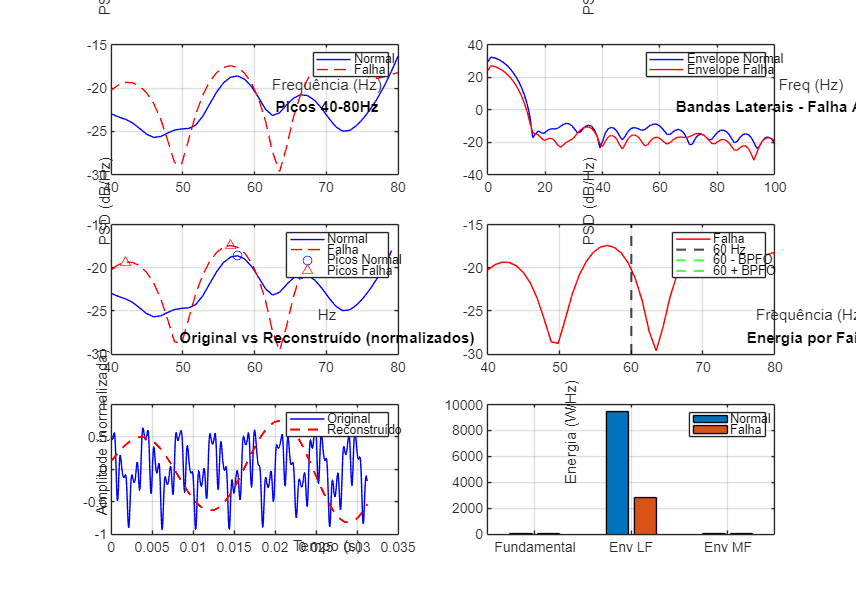


%% GRÁFICO DE ENERGIA
% Mostra visualmente como a energia se redistribui
subplot(3,2,6);

% Vamos preparar os dados pro gráfico de barras
faixas = {};  % Nomes das faixas
energias_norm = [];  % Energias do normal
energias_falha = [];  % Energias da falha

% Adiciona fundamental se tiver dados
if sum(idx_fund) > 0 && E_fund_norm > 0
    faixas{end+1} = 'Fundamental';
    energias_norm(end+1) = E_fund_norm;
    energias_falha(end+1) = E_fund_falha;
end

% Adiciona envelope LF se tiver dados
if sum(idx_env_lf) > 0 && E_env_lf_norm > 0
    faixas{end+1} = 'Env LF';
    energias_norm(end+1) = E_env_lf_norm;
    energias_falha(end+1) = E_env_lf_falha;
end

% Adiciona envelope MF se tiver dados
if sum(idx_env_mf) > 0 && E_env_mf_norm > 0
    faixas{end+1} = 'Env MF';
    energias_norm(end+1) = E_env_mf_norm;
    energias_falha(end+1) = E_env_mf_falha;
end

% Faz o gráfico de barras se tiver algo pra mostrar
if ~isempty(faixas)
    bar_data = [energias_norm; energias_falha]';  % Transpõe pra barras lado a lado
    bar(bar_data);
    set(gca, 'XTickLabel', faixas);  % Coloca os nomes no eixo X
    ylabel('Energia (W/Hz)');
    title('Energia por Faixa');
    legend('Normal', 'Falha');
    grid on;
else
    % Se não tiver dados, avisa
    text(0.5, 0.5, 'Dados insuficientes para gráfico', ...
         'HorizontalAlignment', 'center', 'FontSize', 12);
    title('Energia por Faixa');
end


%% COEFICIENTE DE MODULAÇÃO 
% Isso mede a "força" da falha - quanto maior, pior tá
fprintf('\n--- COEFICIENTE DE MODULAÇÃO ---\n');


--- COEFICIENTE DE MODULAÇÃO ---



% Primeiro acha a amplitude exata da fundamental (60Hz)
idx_fund_centro = find(f >= f_s-0.5 & f <= f_s+0.5, 1);
if ~isempty(idx_fund_centro)
    amp_fund = psd_falha(idx_fund_centro);  % Amplitude da 60Hz
    
    % Agora soma as amplitudes das bandas laterais
    amp_bandas = 0;
    contador = 0;  % Conta quantas bandas a gente achou
    
    % Soma da banda inferior se achou
    if banda_inf_detectada && ~isempty(idx_inf)
        [amp_inf, ~] = max(psd_falha(idx_inf));
        amp_bandas = amp_bandas + amp_inf;
        contador = contador + 1;
    end
    
    % Soma da banda superior se achou
    if banda_sup_detectada && ~isempty(idx_sup)
        [amp_sup, ~] = max(psd_falha(idx_sup));
        amp_bandas = amp_bandas + amp_sup;
        contador = contador + 1;
    end
    
    % Calcula o índice de modulação se tiver dados
    if contador > 0 && amp_fund > 0
        amp_bandas_media = amp_bandas / contador;  % Média das bandas
        mod_index = (amp_bandas_media / amp_fund) * 100;  % Em porcentagem
        
        fprintf('Índice de modulação: %.4f%%\n', mod_index);
        
        % Interpreta o resultado
        if mod_index < 0.1
            fprintf('Diagnóstico: Falha incipiente (tá começando agora)\n');
        elseif mod_index < 1
            fprintf('Diagnóstico: Falha moderada\n');
        else
            fprintf('Diagnóstico: Falha severa (já tá avançada)\n');
        end
    else
        fprintf('Não foi possível calcular coeficiente de modulação\n');
    end
end

Índice de modulação: 78.7651%


Diagnóstico: Falha severa (já tá avançada)



%% RESUMO FINAL

fprintf('========================================\n');


% Verifica se achou assinatura de falha
if banda_inf_detectada || banda_sup_detectada
    fprintf('✓ ASSINATURA DE FALHA DETECTADA\n');
    fprintf('✓ Bandas laterais presentes\n');
else
    fprintf('✗ Assinatura de falha NÃO detectada\n');
end

✓ ASSINATURA DE FALHA DETECTADA


✓ Bandas laterais presentes



% Verifica se o envelope aumentou muito
if aumento_env > 10  % Se aumentou mais que 10%, é significativo
    fprintf('Aumento significativo no envelope\n');
else
    fprintf('Sem aumento significativo no envelope\n');
end

Sem aumento significativo no envelope
